% IOE 511/MATH 562, University of Michigan
% Code written by: Minghao Chen

% Script to run code
% close all figures, clear all variables from workspace and clear command
% window
% close all
clear;clc;clf
format long
addpath(genpath('Methods'));
addpath(genpath('TrustRegion'));
addpath(genpath('Problems'));
addpath(genpath('Linesearch'));
addpath((genpath('Dataset')));
addpath((genpath('Output')));
 

tic
rng(0);
% set problem (minimal requirement: name of problem)
problem.name = "genhumps_5";
problem.x0 = [1;zeros(9,1)];
problem.n = length(problem.x0);
problem.memory = 5;


% set method (minimal requirement: name of method)
method.name = 'GradientDescentW'; % option: GradientDescent, Newton, BFGS, L-BFGS
%method.options.constant_step_size = 1e-3;

% set options   
options.term_tol = 0.000001;
options.max_iterations = 1000;
% fstar = 1;

% h= waitbar(0,'Please wait...');
% run method and return x^* and f^*
[x,f,k,delta,norm_g] = optSolver(problem,method,options);
disp(x)

   1.004300019217025
   1.008646883896846



% output
fig_name = strcat(problem.name,'_',method.name,'_','.png');
result_name = strcat(problem.name,'_',method.name,'_','.mat');

timeElapsed = toc; 
fprintf('%15s %15s %15s %15s','Iteration','Func val','Norm Grad','CPU Seconds');

      Iteration        Func val       Norm Grad     CPU Seconds

fprintf('%15d %15.4e %15.4e %15.4f',k,f,norm_g,timeElapsed); 

           1000      1.8571e-05      5.6711e-03          0.4726

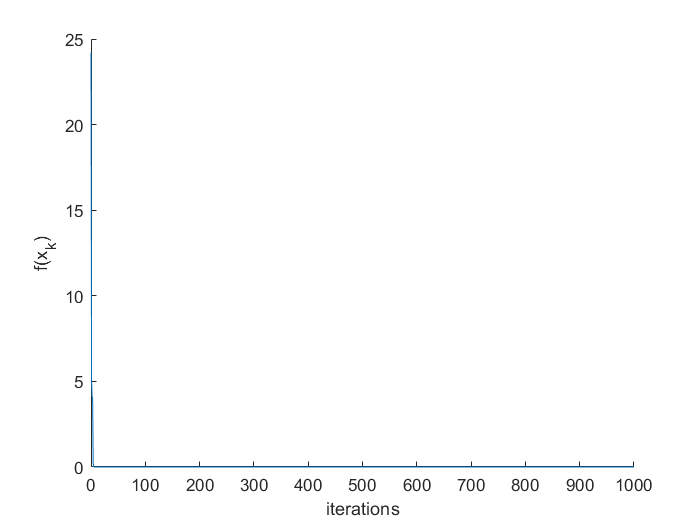


result = {'k','f','norm_g','timeElapsed';k,f,norm_g,timeElapsed};
save(strcat('Output\',result_name'), "result");

% plot the difference between fx and fx v.s. iterations^*
figure(1)
plot(0:k,delta(1:k+1));
%title("Function Value");
xlabel("iterations");
ylabel("f(x_k)");
box off
hold off

exportgraphics(gcf,strcat('Output\',fig_name'),'Resolution',500);